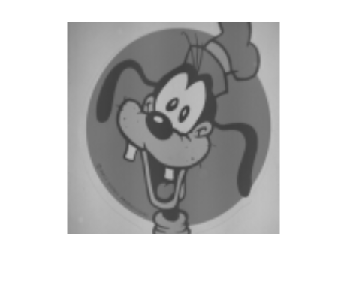

clc;clear all
go=rgb2gray(imread('goofy.png'));
z=zeros(282);

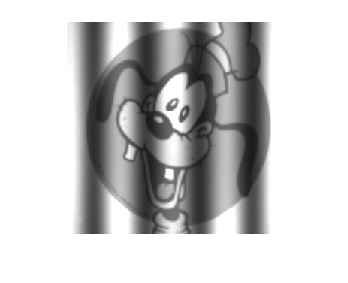

for i=1:282
    y3(1,i)=cos((360/70.5)*i*pi/180);
end
for j=1:282
    y3(j,:)=y3(1,:);
end
y3=0.65*y3+1.05;
yc=y3.*double(go)/255;
imshow(yc) %%goofy cosine

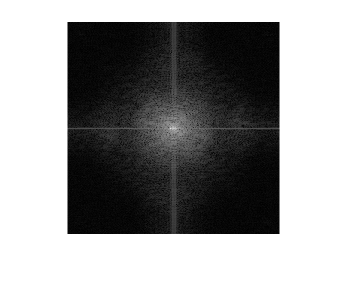

yf=fftshift(fft2(yc));
fftshow(yf) %%%four

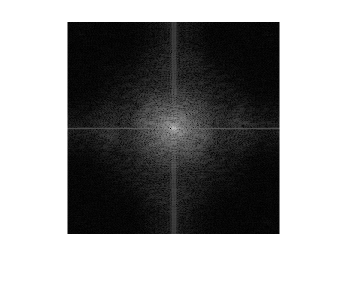

tt=zeros(282);
tt=tt+1;
tt(142,138)=0;
tt(142,146)=0;
tt(142,138:146)=tt(142,138:146).*0.7;
tt(142,142)=1.1;
y=yf.*tt;
figure,fftshow(y)

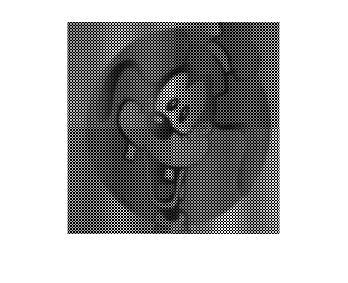

y=ifft2(y);
imshow(y)